%% Método de Galerkin para Black-Scholes con expansión de Hermite
% Basado en el artículo de Baustian, Filipová y Pospíšil
% Versión reorganizada y corregida (operadores elemento a elemento)

clear; close all; clc;
format long
%% 1. Parámetros del modelo y de la opción
r     = 0.05;       % Tasa de interés libre de riesgo
sigma = 0.2;        % Volatilidad constante
K     = 100;        % Precio de ejercicio (strike)
T     = 1;          % Tiempo hasta el vencimiento (en años)
S     = 100;

precio_exacto = blsprice(S,K,r,T,sigma);

%figure
%plot(1:5:200,precio_exacto,'-r*')

% Parámetros de la discretización
%M     = 200;             % Número de polinomios de Hermite (M+1 términos, desde 0 hasta M)

%% 2. Definición de funciones anónimas que dependen de los parámetros

% Payoff de la call en variable x = log(S)
payoff_call = @(x) max(exp(x) - K, 0);

M_vals = 5:5:200;
precio_aprox = zeros(size(M_vals))

precio_aprox =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for idx = 1:length(M_vals)
    M = M_vals(idx);
    
    L = 10;  % Límite para la integral (suficientemente grande dado el decaimiento exponencial)
    fprintf('Calculando coeficientes iniciales para M = %d...\n', M);
    c0 = zeros(M+1, 1);
    for k = 0:M
        % Definimos el integrando como una función anónima que usa payoff_call y hermite
        integrando = @(x) payoff_call(x) .* hermite(x, k) .* exp(-x.^2);
        % Integramos numéricamente
        valor_integral = integral(integrando, -L, L, 'RelTol', 1e-8, 'AbsTol', 1e-10);
        % Factor de normalización
        norm_factor = 2^k * factorial(k) * sqrt(pi);
        c0(k+1) = valor_integral / norm_factor;
    end

%% 4. Construcción de la matriz del sistema de EDOs (matriz D)
% De la ecuación: c' + D c = 0, con D(j+1,i+1) = (1/(2^j j! sqrt(pi))) B(H_i, H_j)
% Usamos la fórmula simplificada (29):
% D(j+1,i+1) = i*(sigma^2 - 2*r) * delta(i, j+1) - 2*i*sigma^2*(j+1) * delta(i, j+2) + r * delta(i,j)
% donde i, j son índices desde 0 (grado del polinomio).
    
    D = zeros(M+1, M+1);
    for i = 0:M
        for j = 0:M
            term1 = i * (sigma^2 - 2*r) * (i == j+1);      % delta(i, j+1)
            term2 = -2 * i * sigma^2 * (j+1) * (i == j+2); % delta(i, j+2)
            term3 = r * (i == j);                           % delta(i, j)
            D(j+1, i+1) = term1 + term2 + term3;
        end
    end
    
    % La ecuación es dc/dtau = -D * c, así que la matriz para la exponencial es -D.
    A = -D;
    
    %% 5. Solución del sistema de EDOs en tau = T (vencimiento)
    % c(tau) = expm(A * tau) * c0
    c_T = expm(A * T) * c0;
    
    %% 6. Evaluación de la solución aproximada u_M(x, T) en puntos de interés
    % Definimos los puntos x donde queremos evaluar (por ejemplo, para distintos moneyness)
    %gamma = linspace(0.5, 2, 200);  % moneyness S/K
    %gamma = 1;  % moneyness S/K
    %S_vals = gamma * K;
    %S_vals = S;
    x_vals = log(S);
    
    % Evaluamos la aproximación: u_M = sum_{k=0}^M c_k(T) H_k(x)
    u_aprox = zeros(size(x_vals));
    
  

    for k = 0:M
        u_aprox = u_aprox + c_T(k+1) * hermite(x_vals, k);
    end
    

    % Convertimos a precio en S (recordar que u(x,t) = V(S,t))
    precio_aprox(idx) = u_aprox;

    


end

Calculando coeficientes iniciales para M = 5...
Calculando coeficientes iniciales para M = 10...
Calculando coeficientes iniciales para M = 15...
Calculando coeficientes iniciales para M = 20...
Calculando coeficientes iniciales para M = 25...
Calculando coeficientes iniciales para M = 30...
Calculando coeficientes iniciales para M = 35...
Calculando coeficientes iniciales para M = 40...
Calculando coeficientes iniciales para M = 45...
Calculando coeficientes iniciales para M = 50...
Calculando coeficientes iniciales para M = 55...
Calculando coeficientes iniciales para M = 60...
Calculando coeficientes iniciales para M = 65...
Calculando coeficientes iniciales para M = 70...
Calculando coeficientes iniciales para M = 75...
Calculando coeficientes iniciales para M = 80...
Calculando coeficientes iniciales para M = 85...
Calculando coeficientes iniciales para M = 90...
Calculando coeficientes iniciales para M = 95...
Calculando coeficientes iniciales para M = 100...
Calculando coeficien

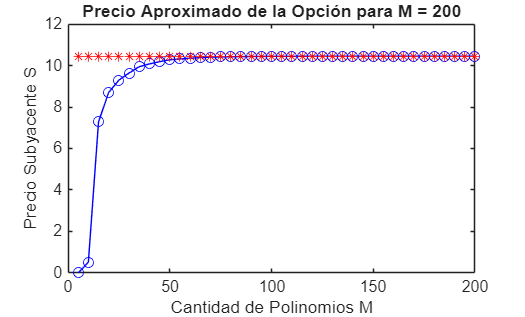


% Graficar el precio aproximado en función del precio subyacente S
figure;
plot(M_vals, precio_aprox, '-bo');
hold on
plot(M_vals,precio_exacto,'-r*')
xlabel('Cantidad de Polinomios M');
ylabel('Precio Subyacente S');
title(sprintf('Precio Aproximado de la Opción para M = %d', M));
hold on;


function H = hermite(x, n)
    % Evalúa el polinomio de Hermite de grado n (físico) en los puntos x.
    % Usa la recurrencia: 
    % H_0 = 1, 
    % H_1 = 2x, 
    % H_{k+1} = 2x H_k - 2k H_{k-1}
    if n == 0
        H = ones(size(x));
    elseif n == 1
        H = 2 * x;
    else
        H_prev = ones(size(x));  % H_0
        H_curr = 2 * x;           % H_1
        for k = 1:n-1
            H_next = 2 * x .* H_curr - 2 * k * H_prev;
            H_prev = H_curr;
            H_curr = H_next;
        end
        H = H_curr;
    end
end

